%% Sistema Incierto

clear
clc

A = [0, 1;-3, -4]

A =      0     1
    -3    -4


B = [0; 1];
C = eye(2);%[[1, 0]]
D = [0];

sys = ss(A, B, C, D)


sys =
 
  A = 
       x1  x2
   x1   0   1
   x2  -3  -4
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



Q = [10 0;0 1];
R = 1;

[K,S,P] = lqr(sys,Q,R)

K =     1.3589    0.4405


S =     7.3556    1.3589
    1.3589    0.4405


P =    -1.4649
   -2.9756



Sys_CL = feedback(sys,K)


Sys_CL =
 
  A = 
           x1      x2
   x1       0       1
   x2  -4.359   -4.44
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



eig(Sys_CL)

ans =    -1.4649
   -2.9756


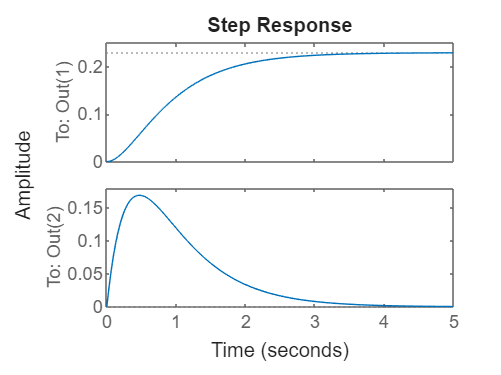


figure;
step(Sys_CL)



%Ver señal de control

Sys_control = feedback(K*sys,1)


Sys_control =
 
  A = 
           x1      x2
   x1       0       1
   x2  -4.359   -4.44
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
           x1      x2
   y1   1.359  0.4405
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


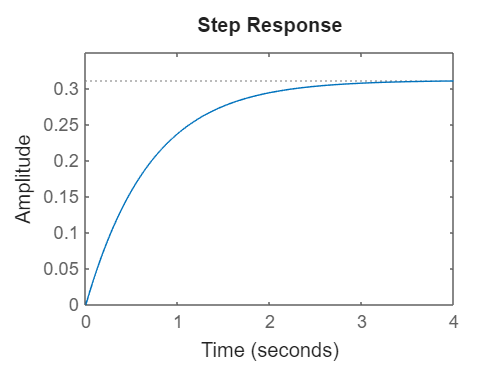


figure;
step(Sys_control)


% Kt = 0.31739;
% Ke = 0.46839;
% Ra = 6.8562;
% B = 1.1278e-3;
% J = 1.45e-3;
% 
% N = 48;
% 
% sysM = ss(tf(Ra,[Ra*J Ke*Kt+Ra*B 0]));
% sysE = ss(tf(48*(Kt/Ra)));

%% Planta Generalizada

M1 = 1.35;
A1 = 0.001;
Wb1 = 15;

M3 = 0.007;
A3 = 2.5;
Wb3 = 2*pi*140;

Wp      = 1*tf(1,1);
W1      = tf([1/M1 Wb1],[1 A1*Wb1]);
W2      = 0.05*tf(1,1);
W3      = tf([1/M3 Wb3],[1 A3*Wb3]);
Wn      = 0.01;

systemnames     = 'sysM sysE Wp Wn W1 W2 W3';
inputvar        = '[ p; n ; r ; u]';
outputvar       = '[ W1; W2 ; W3;-sysM - Wn + r]';
input_to_sysM   = '[-Wp + sysE]';
input_to_sysE   = '[u]';
input_to_Wn     = '[n]';
input_to_W1     = '[-sysM - Wn + r]';
input_to_W2     = '[sysE]';
input_to_W3     = '[sysM]';
input_to_Wp     = '[p]';

sysnom_ic = sysic;

Error using sysic (line 107)
The system variable sysM is not found in the workspace.


%% Controlador

ncont = 1;
nmeas = 1;
[K1,sys_CL,gam1,info] = hinfsyn(sysnom_ic,nmeas,ncont);

%% Lazo cerrado SIN filtros
display('Polos del controlador')
eig(K1)

sysnom = (sysE - Wp)*sysM;

L  = sysnom*K1; % funcion  de lazo directo

sysnom_CL = feedback(L,1);

figure (1)
step(sysnom_CL);

%% Comprobacion W1

S = feedback(1,L);
figure (2)
bodemag(S,'r');
hold on
bodemag(1/W1,'g');

%% Comprobacion W2

S = feedback(1,L);
figure(3)
bodemag(S*K1,'r');
hold on
bodemag(1/W2,'g');

%% Comprobacion W3

T = feedback(L,1);
figure (4)
bodemag(T,'r');
hold on
bodemag(1/W3,'g');

%% Calculo del controlador digital

Kd = c2d(K1,0.0001);

display('Matrices Controlador Discreto')
for i = 1:4
    for j = 1:4
        display(['A[' num2str(i-1) '][' num2str(j-1) '] = ' num2str(Kd.a(i,j)) ';'])
    end
end

for j = 1:4
    
    display(['B[' num2str(j-1) '][' num2str(0) '] = ' num2str(Kd.b(j,1)) ';'])
end

for i = 1:4

    display(['C[0][' num2str(i-1) '] = ' num2str(Kd.c(i)) ';'])
end